# Numerical Experiment on Error of HHL

First we initialize the clock registers to uniform superposition state, and b to random state.

## Initial conditions

nc = 4;
nb = 1;

mat_A = gpuArray([1 3; 3 1]);
vec_b = [1 ; 0];
vec_b = gpuArray(vec_b / norm(vec_b));
% vec_c = ones(2^nc, 1);
vec_c = zeros(2^nc, 1);
vec_c(1) = 1;
vec_c = gpuArray(vec_c / norm(vec_c));

vec_cb = kron(vec_c,vec_b);
vec_cb = vec_cb / norm(vec_cb);
% whos vec_cb
disp("Initially: ");

Initially: 


vec_cb


vec_cb =

     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



## Hardmard gates

H = gpuArray([1 1; 1 -1] / sqrt(2));
Hn_unitary = H;
for j = 2:nc
    Hn_unitary = kron(Hn_unitary, H);
end

Hn_unitary = kron(Hn_unitary, eye(2^nb));

vec_cb = Hn_unitary * vec_cb;
disp("After Hardmard gates: ");

After Hardmard gates: 


vec_cb


vec_cb =

    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0
    0.2500
         0



## Controlled unitaries


t0 = 2*pi / 2^nc;
for j = 1:nc
    t = t0 * 2^(j - 1);
    mat_iAt = 1i * mat_A * t;
    mat_expiAt = expm(mat_iAt);
    
    ctrl_set = [0 0; 0 1];
    ctrl_unset = [1 0; 0 0];
    
    c_unitary_set = gpuArray(kron(kron(ctrl_set, eye(2^(j - 1))), mat_expiAt));
    c_unitary_unset = gpuArray(kron(kron(ctrl_unset, eye(2^(j - 1))), eye(2^nb)));

    c_unitary = kron(eye(2^(nc - j)), c_unitary_set + c_unitary_unset);

    % apply c_unitary to the system state
    vec_cb = c_unitary * vec_cb;
end
disp("After controlled unitaries: ");

After controlled unitaries: 


vec_cb


vec_cb =

   0.2500 + 0.0000i
   0.0000 + 0.0000i
   0.0884 + 0.0366i
  -0.0884 + 0.2134i
  -0.1250 - 0.1250i
  -0.1250 + 0.1250i
  -0.0884 - 0.2134i
   0.0884 - 0.0366i
  -0.0000 - 0.0000i
   0.2500 + 0.0000i
  -0.0884 + 0.2134i
   0.0884 + 0.0366i
  -0.1250 + 0.1250i
  -0.1250 - 0.1250i
   0.0884 - 0.0366i
  -0.0884 - 0.2134i
   0.2500 + 0.0000i
  -0.0000 - 0.0000i
   0.0884 + 0.0366i
  -0.0884 + 0.2134i
  -0.1250 - 0.1250i
  -0.1250 + 0.1250i
  -0.0884 - 0.2134i
   0.0884 - 0.0366i
  -0.0000 - 0.0000i
   0.2500 + 0.0000i
  -0.0884 + 0.2134i
   0.0884 + 0.0366i
  -0.1250 + 0.1250i
  -0.1250 - 0.1250i
   0.0884 - 0.0366i
  -0.0884 - 0.2134i



## QFT diagger

F = gpuArray(dftmtx(2^nc) / sqrt(2^nc));
qft_diagger_unitary = kron(F, eye(2^nb));
vec_cb = qft_diagger_unitary * vec_cb;

disp("After QFT diagger: ");

After QFT diagger: 


vec_cb


vec_cb =

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.5000 - 0.0000i
   0.5000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.5000 + 0.0000i
  -0.5000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i



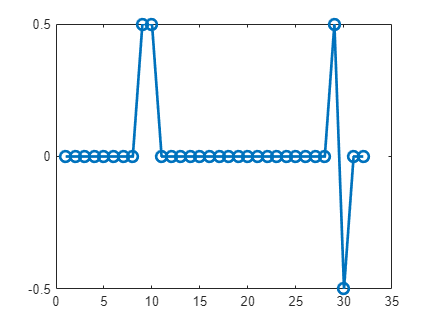


idx = 1:length(vec_cb);
figure;
plot(idx, vec_cb,'-o', 'LineWidth', 2, 'MarkerSize', 8);

## Controlled rotation

vec_s = [1; 0]; % |0>
vec_scb = kron(vec_s, vec_cb);

for j = 1:2^nc-1
    ket_j = zeros(2^nc, 1);
    ket_j(j+1) = 1; %% must perform for each number because inverse is not additive
    ket_j_outer = gpuArray(ket_j * ket_j');

    compliment = gpuArray(eye(2^nc) - ket_j_outer);

    % support for negative eigenvalues
    lambda = 1;
    if(j < 2^(nc - 1))
        lambda = j;
    else
        lambda = j - 2^nc; % negative eigenvalue
    end
    
    cos = sqrt(1 - 1/lambda^2);
    sin = 1/ lambda;
    rotation = [cos -sin; sin cos];

    c_r_unitary = kron(kron(rotation, ket_j_outer)+ kron(eye(2), compliment), eye(2^nb));
    vec_scb  = c_r_unitary * vec_scb;
end

Now we perform the post selection.

vec_cb = vec_scb(2^(nc + nb)+1:end);
vec_cb = vec_cb / norm(vec_cb);
disp("After controlled rotation");

After controlled rotation


vec_cb


vec_cb =

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.3162 - 0.0000i
   0.3162 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.6325 - 0.0000i
   0.6325 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i



Next we perform the inverse qpe to clean up.

## QPE inverse

qft_unitary = kron(conj(F), eye(2^nb));
vec_cb = qft_unitary * vec_cb;
% controlled unitary diagger
for j = nc:-1:1
    t = t0 * 2^(j - 1);
    mat_iAdgt = -1i * mat_A * t;
    mat_expiAdgt = expm(mat_iAdgt);
    
    ctrl_set = [0 0; 0 1];
    ctrl_unset = [1 0; 0 0];
    
    c_unitary_set = kron(kron(ctrl_set, eye(2^(j - 1))), mat_expiAdgt);
    c_unitary_unset = kron(kron(ctrl_unset, eye(2^(j - 1))), eye(2^nb));

    c_unitary = kron(eye(2^(nc - j)), c_unitary_set + c_unitary_unset);
    
    % apply c_unitary to the system state
    vec_cb = c_unitary * vec_cb;
end

vec_cb = Hn_unitary * vec_cb;
disp("After QPE inverse: ");

After QPE inverse: 


vec_cb


vec_cb =

  -0.3162 - 0.0000i
   0.9487 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i



## Partial trace to get answer

note that we can perform partial trace like this is because initially we set b to be |0>.

vec_x = vec_cb(1:2^nb);
vec_x = vec_x / norm(vec_x);
disp("The solution to Ax = b is: ");

The solution to Ax = b is: 


vec_x


vec_x =

  -0.3162 - 0.0000i
   0.9487 - 0.0000i



## Check answer

disp("Ax = ");

Ax = 


mat_A * vec_x / norm(mat_A * vec_x)


ans =

   1.0000 - 0.0000i
  -0.0000 - 0.0000i




disp("b = ");

b = 


vec_b


vec_b =

     1
     0

